# Lab 9.1: PID Control Design for Buck Converters

## Tim Roche, Jacob Weber, Elisabeth Davis

## Response of the Buck Converter

Tapping back into the first few labs you did in the semester, you need to get an understanding of the system you are trying to control. To do this, you can use the following transfer function (which I recommend deriving on your own) to see the step and impulse responses of the circuit. 


$$\frac{V_o}{D} = \frac{\frac{V_{in}}{LC}}{s^2+s\left(\frac{1}{R_oC}+\frac{R_L}{L}\right)+\left(\frac{1}{LC}+\frac{R_L}{R_oLC}\right)}$$


For an example system, you can use the following values for your system.

- 
$$V_{in} = 24V$$


- 
$$V_{out} = 18V$$


- 
$$R_{load} = 100\Omega$$


- 
$$F_s = 50kHz$$


- 
$$L = 1.7mH$$


- 
$$C = 0.75\mu F$$


- ESR of Inductor $R_L = 0.08\Omega$

- ESR of Capacitor $R_C = 0.03\Omega$

*Insert whatever you need here, including code blocks, pictures, etc.*

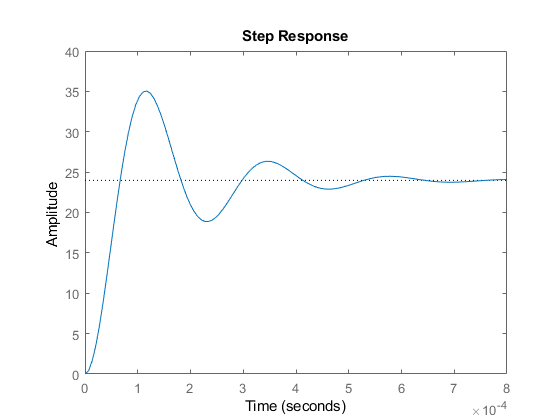

warning('off')

Vin = 24;
L = 1.7*10^-3;
C = 0.75*10^-6;
R_load = 100;
R_L = 0.08;
vinNoise = 0;
syms s;
G = tf([(Vin)/(L*C)], [1 (1/(R_load * C) + R_L/L) (1/(L*C) + R_L/(R_load*L*C))]);
figure(1);
step(G);

It can clearly be seen that without the feedback loop, the buck converter transfer function produces some steady state error in addition to a large amount of overshoot. 

stepinfo(G)

ans = struct with fields:
        RiseTime: 4.4791e-05
    SettlingTime: 5.8830e-04
     SettlingMin: 18.8847
     SettlingMax: 35.0458
       Overshoot: 46.1410
      Undershoot: 0
            Peak: 35.0458
        PeakTime: 1.1702e-04


In addition, it can be seen that the rise time is 0.0447ms and the settling time is 0.588ms. These times could change with different series resistances or slightly different values for capcitors or resistors. To force the transfer function of any off-the-self buck converter to have exactly the charecteristics demanded, a control system will need to be implimented around it.

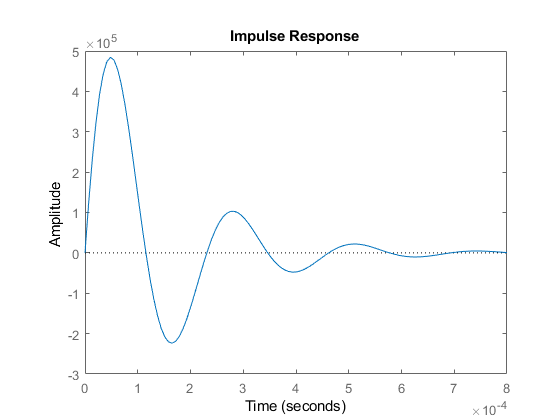

figure(2);
impulse(G);

The figure above shows the impulse response of the transfer function of the buck converter. It is easy to see in this figure the large amount of overshoot that the system has uncompensated by a control system. 

## Controlling the transient response of the Buck Converter

Now that you hopefully have a decent idea of how this circuit is meant to operate, you can begin to tune the response of the system to fit your needs. For now, we are holding the output resistance (load current) steady, but we will eventually be changing that to really see if the control loop is working. 

There is literally an entire course we offer on how to pick these values and its impact on system performance, but for now, you should tune a PID controller to force your Buck Converter to have the following transient characteristics. These can be dependent on things like switching characteristics of the FETs, load type, input impedence, etc.

- Steady State Error = 0%

- Rise Time = 0.719ms

- Settling Time = 1.32ms

- % Ripple = 0.56%

- Peak Time = 1ms

You will need to tune the PID which is already in the Simulink file. Make sure you document how you are go about your tuning and the steps you took.

______

The parameters given above are assumed:

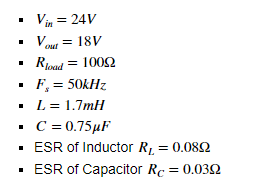

**Attempted Hand Calculation**

We start with the given parameters to find the desired coordinates to be on the Root Locus

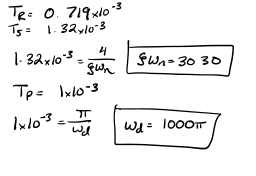

Now we find summation of angles from the open loop poles to that point

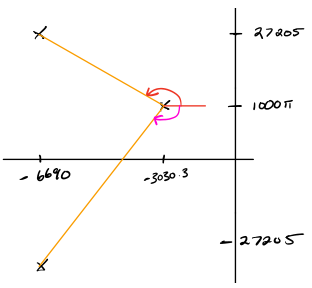

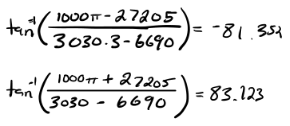

This angle equals -1.771 degrees. We must add up to 2 zeros to make it an odd multiple of 180. Lets find the summation of the angles of the two zeros we are going to add. 

To advoid undershoot, I would like both of these zeros to be in the left half plane. First, I need to see at what angle the right half plane starts.

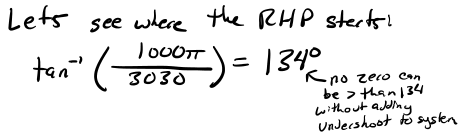

So neither zero can have an angle greater than 134 to not be in the right half plane. Normally, we would start by adding in one zero to fully compensate the system and use the second zero to counteract the pole we need to place at the origin to remove steady state error. However, since the angle sum needs to be greater than 180 such a method is not possible. We must use both the zeros to reach back to an odd multiple of 180. With this in mind, lets add in the pole to the angle summation to get a full picture of the angles the zeros will need to be at. Since the pole is going to be at the origin, we know its angle is 134 degrees. 

So the summation of the angles of our zeros will need to add up to be 315.77 degrees. Lets see if its even possible for both of them to be in the left half plane. 

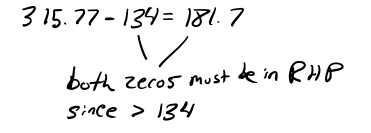

Even if I place a zero directly at the origin as a best case scenerio, the second zero would need to be in the right half plane. Therefore for a compensator made up of non-zero P I and D components, the zeros must be in the right half plane to put the desired parameters on the root locus. 

Even with this in mind, lets do it anyway. I will select 145.79 degrees for one zero and 170 degrees for the other:

Now we need to convert these angles into cordinates in the s-plane:

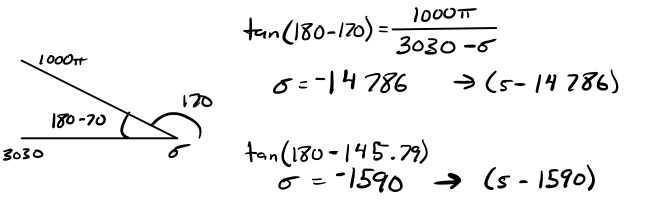

Our system calls for a zero at +14786 and +1590 in the s-plane in addition to a pure integrator to remove SSE. 

Lets add this compensator to our system and plot the Root Locus. The astrisk represents the location of our desired parameters on the Root Locus. 

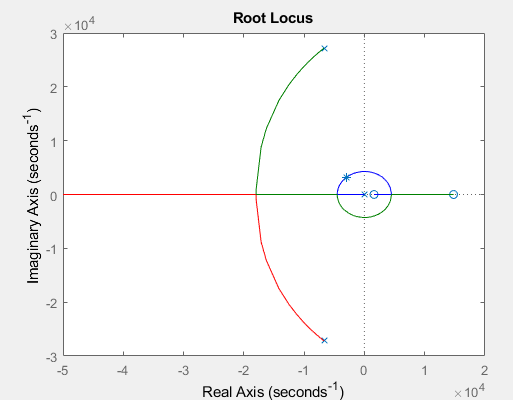

The two zeros place the desired parameters on the root locus. Now lets find the P I and D values. Using MATLAB it is found that the gain at the desired point is approximately 7.3*10^12. 

We observe the step response: 

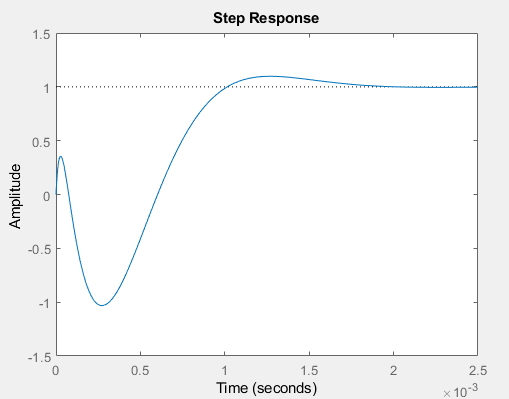

It can be seen that those two zeros in the right half plane add signifigant undershoot to the system.

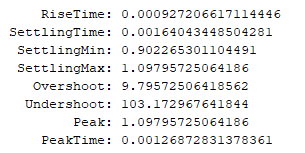

However, we see that the system does approximate the required rise time, settling time, and peak time. But when the sytem is put into the actual buck converter, the 103% undershoot makes the hand-calculated system unfeasible. 

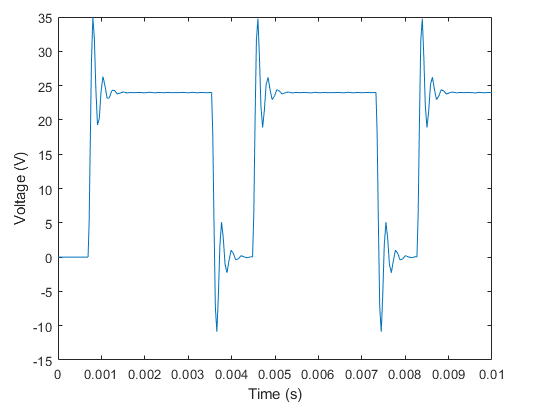

From this hand calculation, it was observed that for this system, having no-zero P I and D parameters would require the two compensating zeros to have their values in the right half plane. Now we try designing a system using computer optimizations. 

**Computer Optimized Calculation**

To tune the PID controller, the simulink PID controller software was used. The objective was to use the computer aided tuning built into simulink to get approximate values and then to fine tune these by hand. Due to the PWM setup in the original buck converter model, the computer could not linearize the model which is required for autotuning. To bypass this limitation, the transfer function provided in the previous set was placed inside a feedback loop as G(s) with a PID compensator placed before it. This model will approximate the performance of the complete model given in the lab. Once tuned the PID settings can be transfered over to the official model. 

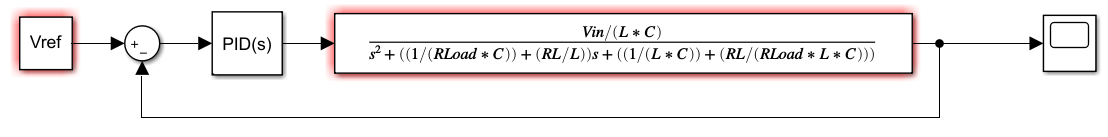

**The model of the buck converter used for automatic tuning**

Once the transfer function version of the buck converter was modeled, the automatic tuning feature of simulink was used. The software contained two dials. One to change the response time of the step response and one to change the transient behavor.

**The dials as seen in the autotuning software**

In a window next to the dials, simulink outputted the current system charecteristics. Using these dials and monitoring the system charecteristics, the system was succesfully tuned to the specs seen in the table below. The final charecteristics of the system yielded an I of 119 with 0 P or D components. It is essential for there to be an intergration componetant as this pole at the origin removes the steady state error from the step response.

**Tuned PID Values:**

**P: **0 **I: **119.504 **D: **0

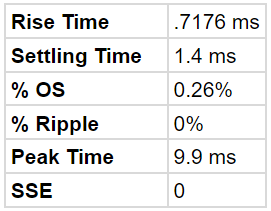

**Table of achieved system parameters**

As it can be seen in the table above, the PID system developed was able to nearly match the desired charecteristics. The achieved rise time was 0.718, nearly the .719 desired.  The PID system also achieved zero steady state error since the system was forced to zero through the addition of a pole at s=0 by adding an integrating component to the PID system. However, the peak time was 9.9ms, higher than the desired 1ms. 

Finally, the transfer function model PID settings  where moved into the provided buck converter model. The same metrics as seen in the estimated Amodel were observed. The transient and steady state behavor of the provided model with the tuned PID settings can be seen in the figures below generated by the code block. 

At first the buck converter model provided did not work properly. It seems the issue was tracked down to be due to the implimentation of the PWM module. The module was replaced with an off-the-self matlab module. In addition, the integrator portion of the PID system was equipped with anti-windup to prevent the integrator having a hard time recovering if the output become saturaterated since it "remembers" these very high values. The anti windup implimented was a simple clamp that clamps the output from 0 to 1. The final buck converter can be seen below.

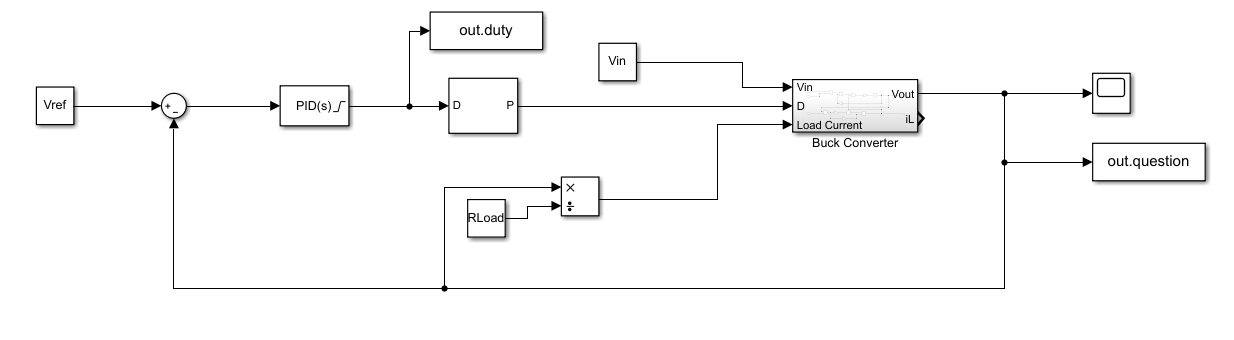

**The Buck Converter Simulink Model**

warning('off')

Vref = 18;
Vin = 24;
RLoad = 100;
vinNoise = 0;
L = 1.7*10^-3;
C = 0.75*10^-6;
RL = 0.08;
RC = 0.03;
fs = 50*10^3;

figure(3)
simOut = sim('BuckConverter.slx','ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


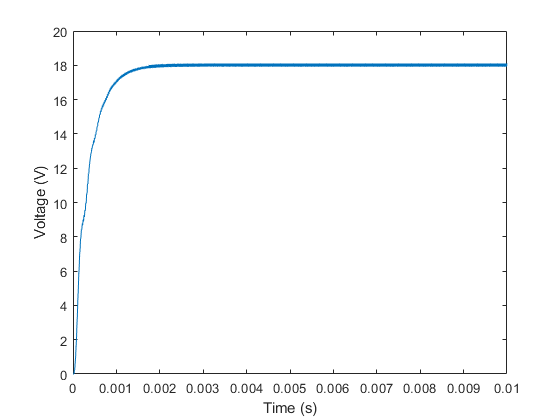

plot(simOut.question.Time, simOut.question.Data);
xlabel("Time (s)");
ylabel("Voltage (V)"); 

As it can be seen, the computer assisted PID values produces a step response with 0 steady state error and shows the charecteristics explained above. There does appear to be some "wobbliness" in the transient response most likely due to the additional pole at s=0. 

## Let's get real with this circuit

One of the biggest assumptions that has been made for you this whole time is that the input voltage is consistent and the load current is consistent as well. I hope you can imagine pretty quickly that you cannot have a system with these perfect situations. Whether it is battery powered, renewables, or other methods of powering the device the input voltage is bound to change over time, but your buck converter still needs to be consistent.

### Variance in Input Voltage

Originally, there was going to be solar panels hooked up to the input, which can varry in voltage, current, and impendance based on the amount of light on them. In order to see the impact of some of these variances, you should probe your newly tuned Buck Converter to see if they still would work in the situation.  For all of these, you should also look at plotting the duty cycle of the system throughout the response, which is basically seeing how your system is responding.

#### DC Offset

To simulate minor change in day-to-day operations such as clouds passing overhead which are slow compared to the response time of the system.

Apply a $\pm 10\%$ offest to the input of your system and plot the response versus the original input voltage. Compare the duty cycles during the transient period and the steadystate period.

Next, apply a $\pm 20\%$ and perform the same analysis.

_______

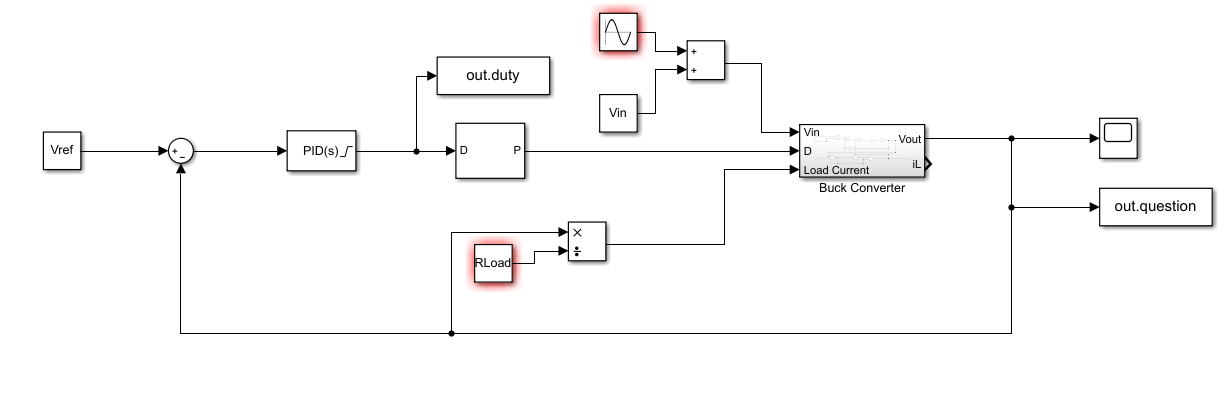

**Circuit Diagram For Experiment**

$\pm 10\%$ **OFFSET**

clf
clear all
clc
warning('off')

multiple = [1 0.9 1.1];
Vref = 18;
Vin_og = 24;
RLoad = 100;
D = 0.45;
vinNoise = 0;
L = 1.7*10^-3;
C = 0.75*10^-6;
RL = 0.08;
RC = 0.03;
fs = 50*10^3;

disp("pm 10%")

pm 10%


figure(4)
plts = [];
hold on;
for m=multiple
    Vin = Vin_og*m;
    simOut = sim('buckConverter.slx');
    p = plot(simOut.question.Time, simOut.question.Data,'DisplayName', "V_{in}*"+m);
    plts = [plts p];
end 

Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


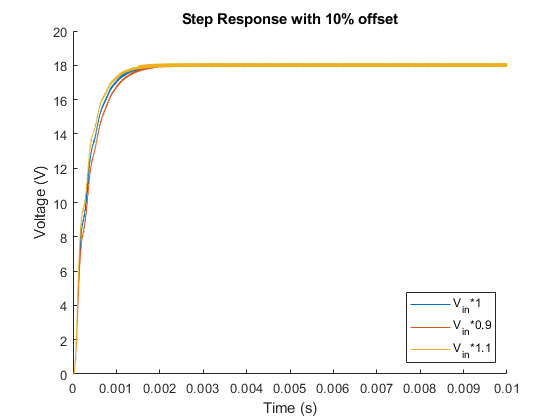

hold off;
xlabel("Time (s)");
ylabel("Voltage (V)"); 
title("Step Response with 10% offset")
legend(plts, 'Location', 'southeast')

As it can be seen in the figure above, the buck converter is able to componsate for a 10% DC swing without signifigantly affecting key system parameters. The effects of the change in input voltage can only be seen as minor wobbles in the transient response. In addition, a higher input causes the system to reach the steady state faster, whereas a lower voltage input caused the system to reach to the steady state slower. 

figure(5)
hold on;
plts = [];
for m=multiple
    Vin = Vin_og*m;
    simOut = sim('buckConverter.slx');
    p = plot(simOut.duty.Time, simOut.duty.Data,'DisplayName', "V_{in}*"+m);
    plts = [plts p];
end 

Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


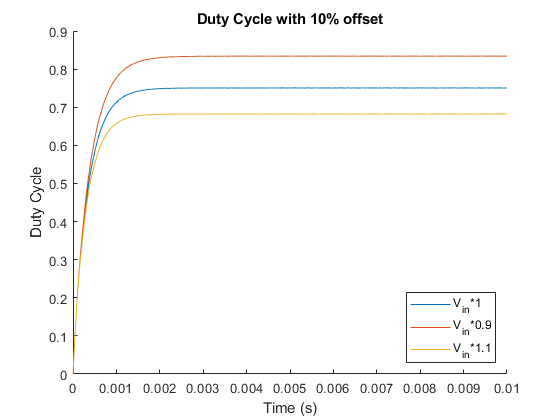


xlabel("Time (s)");
ylabel("Duty Cycle"); 
legend(plts, 'Location', 'southeast')
title("Duty Cycle with 10% offset")
hold off;

As it can be seen in the figure above, the control system componsates by either increasing or decreasing the duty cycle depending on if the input voltage increased or decreased by 10%. When the input voltage increased, the duty cycle decreased by approximately 7%. When the input voltage decreased, the duty cycle increased by approximately 10%. 

$\pm 20\%$**OFFSET**

multiple = [1 0.8 1.2];
figure(6)
disp("pm 20%")

pm 20%


hold on;
plts = [];
for m=multiple
    Vin = Vin_og*m;
    simOut = sim('buckConverter.slx');
    p = plot(simOut.question.Time, simOut.question.Data,'DisplayName', "V_{in}*"+m);
    plts = [plts p];
end 

Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


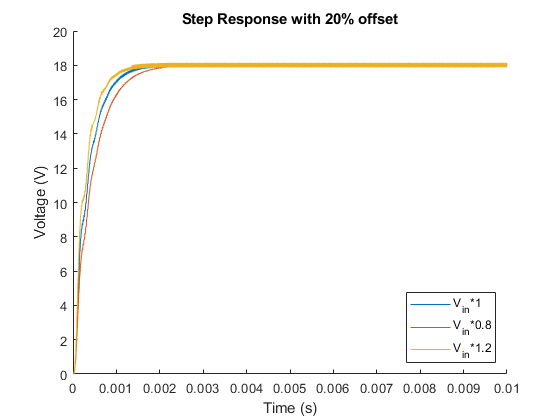

xlabel("Time (s)");
ylabel("Voltage (V)"); 
title("Step Response with 20% offset")
legend(plts, 'Location', 'southeast')
hold off;

As it can be seen in the figure above, when the input voltage is offset by 20% of its expected value, the system manages to componsate at have the steady state value be exactly as expected. However, the transients are observed to be more wobbly then even the 10% offset. It can also be seen that an increase in input voltage caused the system to arrive at the steady state quicker whearas a 20% decrease in voltage caused the system to arrive at the steady state slower. All of these observations where observed about the 10% error system, however, this time each observation is more extreme. However, the system remains stable in both cases. 


figure(7)
hold on;
plts = [];
for m=multiple
    Vin = Vin_og*m;
    simOut = sim('buckConverter.slx');
    p = plot(simOut.duty.Time, simOut.duty.Data,'DisplayName', "V_{in}*"+m);
    plts = [plts p];
end 

Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


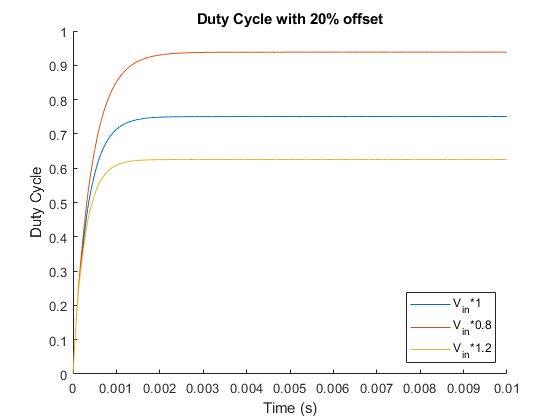


xlabel("Time (s)");
ylabel("Duty Cycle"); 
title("Duty Cycle with 20% offset")
legend(plts, 'Location', 'southeast')
hold off;

Simular to the 10% offset, as the voltage increases the duty cycle decreases and vice versa. However, when compared to the 10% offset the componsation the control system is making are more major. When the voltage decreases by 20%, the system componsates by increasing the duty cycle by 20%. Whereas, when the voltage increases by 20%, the duty cycle decreases by about 10%. However, the system remains stable. 

#### DC with Sinusoid

To account for things like noise from the power lines, environmental noise, etc., we should corrupt our input voltage with a pure sine wave focusing on a few key frequencies which we would be present. 

Apply a 60hz Sine Wave superimposed on the DC input from the original circuit with an amplitude 1/20th of the DC value. Plot the output and compare how well the buck converter rejects the noise. Do the same for 1/10th the DC voltage.

clf
clear all
clc
warning('off')

Vref = 18;
Vin = 24;
RLoad = 100;
D = 0.45;
L = 1.7*10^-3;
C = 0.75*10^-6;
RL = 0.08;
RC = 0.03;
fs = 50*10^3;

vinNoises = [0 (1/20) (1/10)]*Vin;
figure(8)
hold on;
plts = [];
for vinNoise=vinNoises
    simOut = sim('buckConverter.slx');
    p = plot(simOut.question.Time, simOut.question.Data,'DisplayName', "|V_{noise}| = "+vinNoise);
    plts = [plts p];
end

Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


Found algebraic loop containing: 
BuckConverter/Buck Converter/Subtract2
BuckConverter/Buck Converter/Gain3
BuckConverter/Buck Converter/Add
BuckConverter/Divide (algebraic variable)


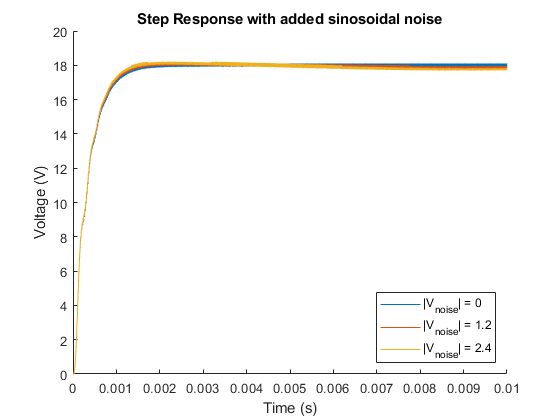

hold off;
legend(plts, 'Location', 'southeast')
title("Step Response with added sinosoidal noise")
xlabel("Time (s)");
ylabel("Voltage (V)");

As seen in the figure above, the buck converter succesfully rejects the sinosoidial noise added due to environmental noises. At both 1/10 and 1/20th the input voltage very little deviation is seen from the uncorrupted signal. However, it is observed that this addition of noise has added a very small amount of steady state error to the output of the system in the form of a sinosoid. However, the magnitude of this noise on the steady state is minimal.

### Noise in the feedback

Since this cirucit depends heavily on the use of feedback, we need to ensure that noise introduced by the switching circuit doesnt corrupt the performance of the output. There are going to be two sources of noise you need to see if there is a resiliance to: Switching Noise, and Random Noise.

#### Switching Noise

Since the FET is swtiching at a particular frequency, this noise (and its harmonics) are going to propegate throughout the circuit, including the feedback path. Using a summing junction, add a sinusoidal source with voltage 1/20th the ideal output voltage, and a frequency of that used in the switching circuit. Plot the output as well as the duty cycle and determine if the system can reject the noise.

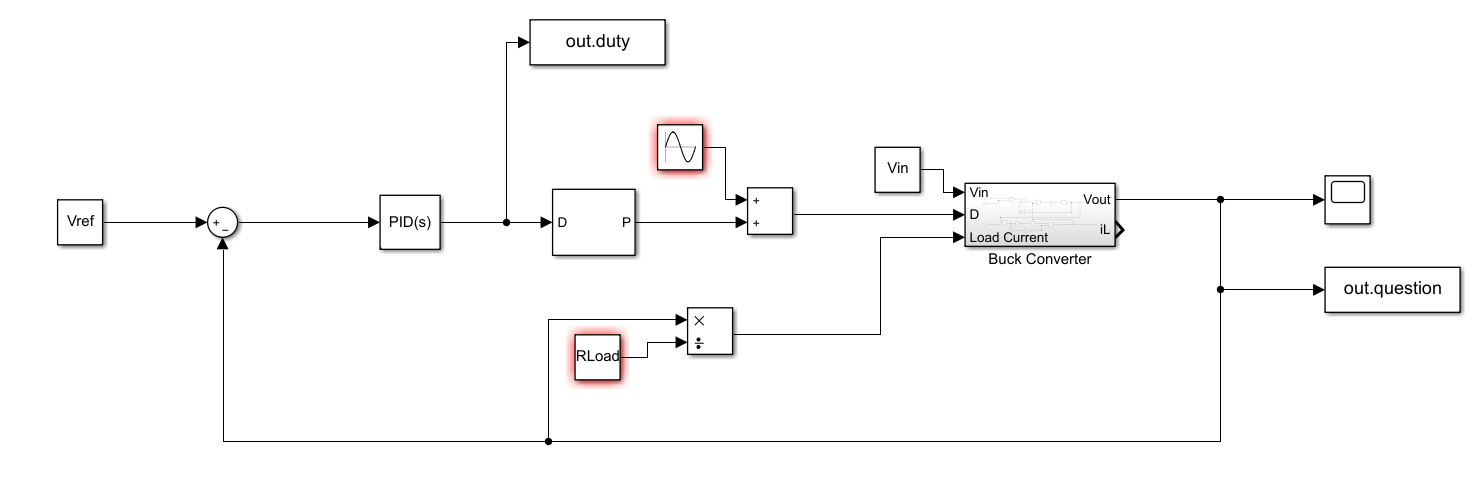

**Circuit Diagram For Experiment**

clf
clear all
clc
warning('off')

Vref = 18;
Vin = 24;
RLoad = 100;
D = 0.45;
L = 1.7*10^-3;
C = 0.75*10^-6;
RL = 0.08;
RC = 0.03;
fs = 50*10^3;
switchNoise = (1/20)*Vref;

figure(9)
simOut = sim('buckConverterFETSine.slx');

Found algebraic loop containing: 
BuckConverterFETSine/Buck Converter/Subtract2
BuckConverterFETSine/Buck Converter/Gain3
BuckConverterFETSine/Buck Converter/Add
BuckConverterFETSine/Divide (algebraic variable)


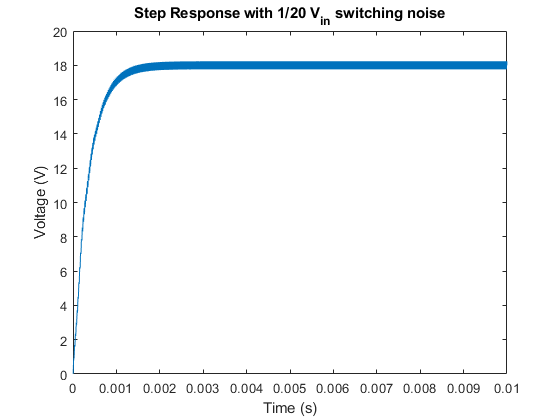

plot(simOut.question.Time, simOut.question.Data);
xlabel("Time (s)");
ylabel("Voltage (V)");
title("Step Response with 1/20 V_{in} switching noise")

As it can be seen in the step reponse above, the system is able to keep the output at approximately 18 volts. However, the output is not constant at 18 volts but instead occilating between 18 volts and about 17.7 volts due to the switching noise. Despite this, the system remains stable. 

figure(10)
simOut = sim('buckConverterFETSine.slx');

Found algebraic loop containing: 
BuckConverterFETSine/Buck Converter/Subtract2
BuckConverterFETSine/Buck Converter/Gain3
BuckConverterFETSine/Buck Converter/Add
BuckConverterFETSine/Divide (algebraic variable)


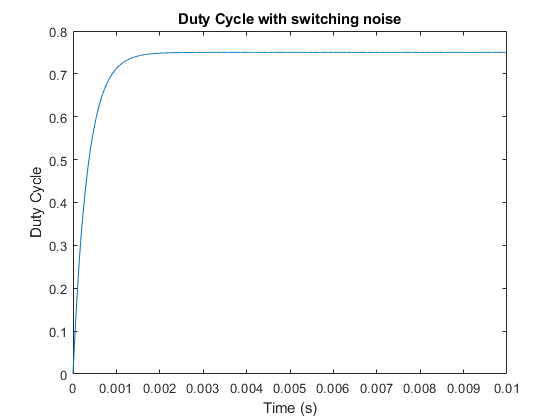

plot(simOut.duty.Time, simOut.duty.Data);
xlabel("Time (s)");
ylabel("Duty Cycle"); 
title("Duty Cycle with switching noise")

As it can be seen in the figure above, the duty cycle of the system with switching noise does not take in account the noise in the system. It remains steady at 0.72. The constant nature of the noise means that its peaks are canceling out with the troughs in the integrator leading to the system not signifigantly accounting for the noise. 

#### Environmental Noise

Do the same as above, but utilize a white noise source instead of a pure sine wave. 

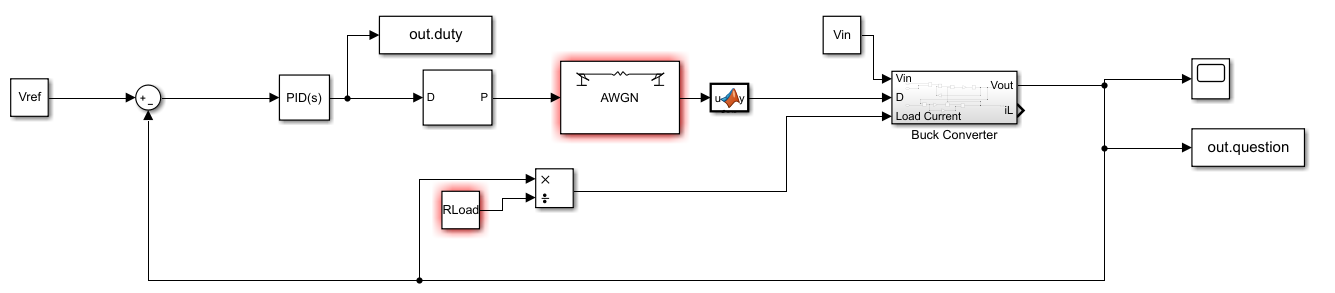

**Circuit Diagram for Experiment**

clf
clear all
clc
warning('off')

Vref = 18;
Vin = 24;
RLoad = 100;
D = 0.45;
L = 1.7*10^-3;
C = 0.75*10^-6;
RL = 0.08;
RC = 0.03;
fs = 50*10^3;
switchNoise = (1/20)*Vref;

figure(10)
simOut = sim('buckConverterEnviron.slx');

Found algebraic loop containing: 
BuckConverterEnviron/Buck Converter/Subtract2
BuckConverterEnviron/Buck Converter/Gain3
BuckConverterEnviron/Buck Converter/Add
BuckConverterEnviron/Divide (algebraic variable)


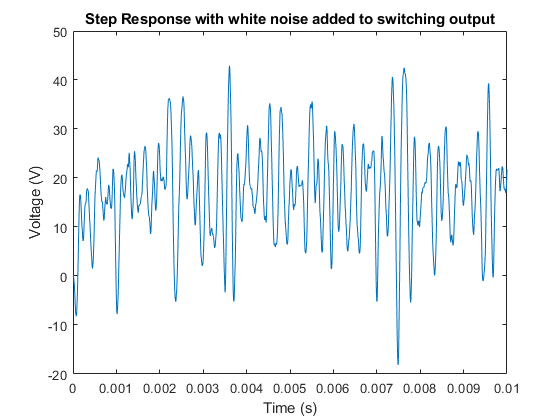

plot(simOut.question.Time, simOut.question.Data);
xlabel("Time (s)");
ylabel("Voltage (V)");
title("Step Response with white noise added to switching output")

As it can be seen, the system cannot handle the white noise being added to the PWM output. The output voltage of the system is seen to ocillate between -10 and 40 voltage semi-randomly. The system is unuseable in this state. 

figure(11)
simOut = sim('buckConverterEnviron.slx');

Found algebraic loop containing: 
BuckConverterEnviron/Buck Converter/Subtract2
BuckConverterEnviron/Buck Converter/Gain3
BuckConverterEnviron/Buck Converter/Add
BuckConverterEnviron/Divide (algebraic variable)


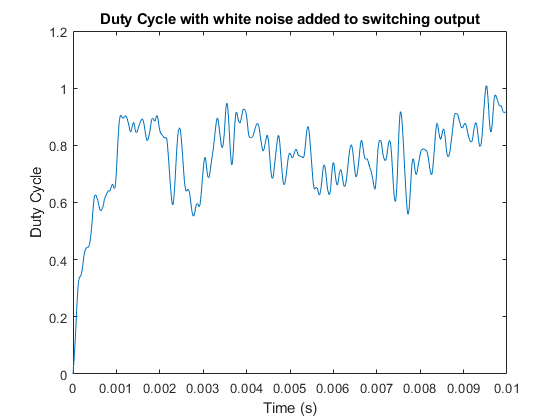

plot(simOut.duty.Time, simOut.duty.Data);
title("Duty Cycle with white noise added to switching output")
xlabel("Time (s)");
ylabel("Duty Cycle");

The duty cycle varies trying to account for the environmental white noise but cannot keep up and remains near 100% duty cycle. 

### Variance in Output

This is truly where the most realistic impact is going to be in your system. Up to this point, the load impedance has not changed, but when you are powering something, the required current needed by the load is going to change based on what it is doing. To help simulate this, I am going to pull from an example in IoT, Low Power Sensor Nodes. These devices mostly sleep throughout the day, only waking up to take measurements and report information. We are going to speed things up a bit and make a sysem which really reports almost too much for some of these applications.

To simulate a node using something like Bluetooth or LoRa to communicate, we are only going to focus on two modes: Sleep, and Transmit. Our node is going to report measurements once every second, which is going to put a heavy draw on the buck converter. For our example sensor node, assume that every second, the system sits idle for 900ms and actively transmits for 100ms. The current draws for these modes are:

- Idle: 0.1mA

- Active: 100mA

Your tasks is to change $R_{Load}$to reflect these changes in current draws and to monitor the performance of the circuit during the periods of transition. You need to ensure that the circuit is performing as expected and is within the performance specs laid out when you designed the controller. Determine the impact of a longer active period on the circuit, and if there would be a point where the circuit would "fail" in providing the correct output voltage.

_________

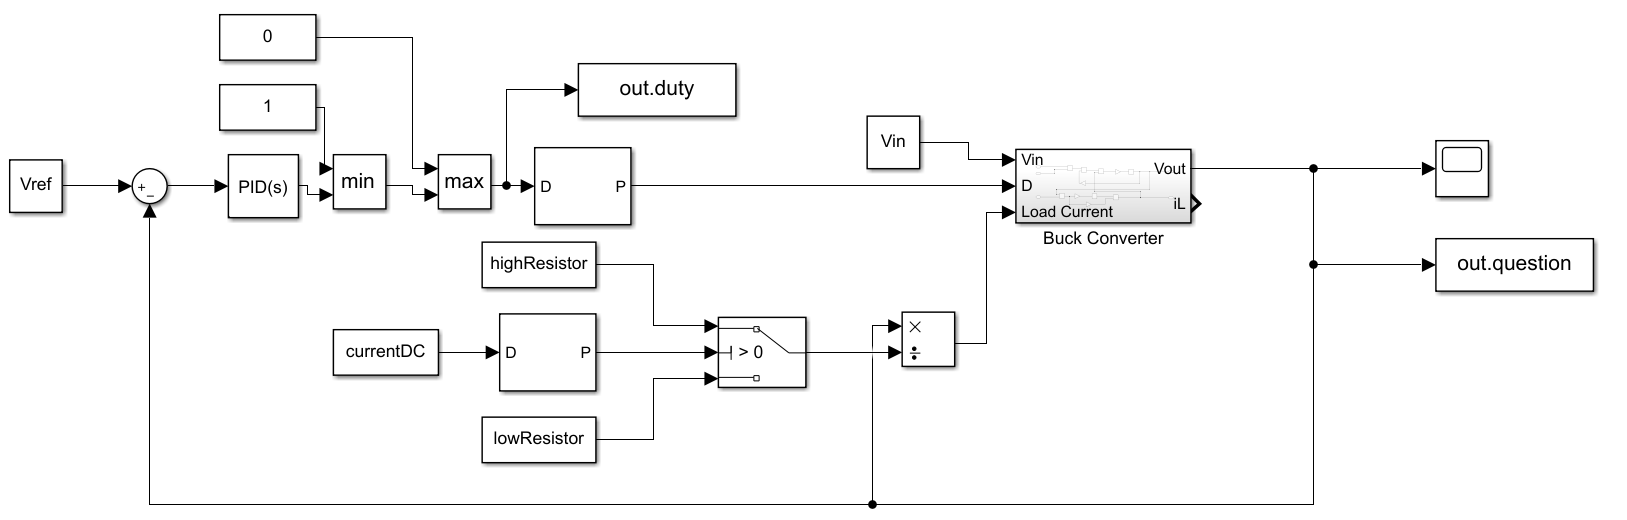

**Circuit Diagram For Experiment**

clf
clear all
clc
warning('off')

Vref = 18;
Vin = 24;
L = 1.7*10^-3;
C = 0.75*10^-6;
RL = 0.08;
RC = 0.03;
fs = 50*10^3;

cycleFreq = 1;
currentDC = 1/10;
lowResistor = Vref/0.1e-3;
highResistor = Vref/100e-3;

figure(12);
simOut = sim('BuckConverterSwitchingR.slx');

Found algebraic loop containing: 
BuckConverterSwitchingR/Buck Converter/Subtract2
BuckConverterSwitchingR/Buck Converter/Gain3
BuckConverterSwitchingR/Buck Converter/Add
BuckConverterSwitchingR/Divide (algebraic variable)


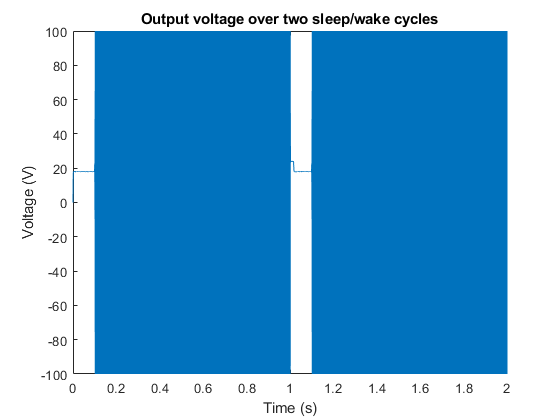

plot(simOut.question.Time, simOut.question.Data);
ylim([-100 100])
xlabel("Time (s)");
ylabel("Voltage (V)");
title("Output voltage over two sleep/wake cycles")

As can be seen in the figure above, the system could not handle the idle current of 0.1mA. At this low of an input current the system went unstable and the output voltage would theroretically occilate between +/- 4000 volts. This is because the PID was tuned with an expected current of 180mA. 0.1mA is 1800 times lower than the current the system was orignally designed for. This lead the output to go unstable. However, for a current draw of 100mA, the system remained stable and was able to output the expected voltage. 

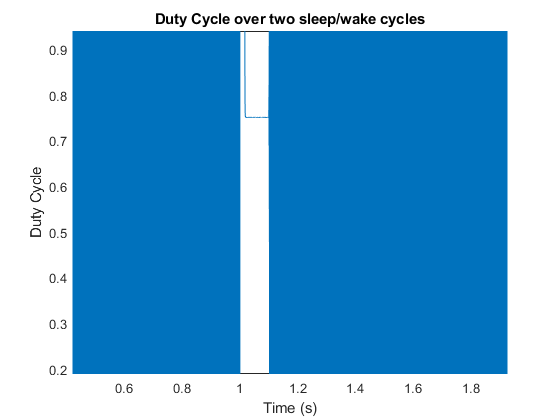

figure(13);
plot(simOut.duty.Time, simOut.duty.Data);
xlabel("Time (s)");
ylabel("Duty Cycle");
title("Duty Cycle over two sleep/wake cycles")

The duty cycle tells the same story the voltage plot does. With a current draw of 100mA, the system was able to keep up cranking up the duty cycle to 0.75 to maintain operation, but when then current draw went to 0.1mA, the system went unstable and the duty cycle began to occilate between 0 and 1. The integral portion of the PID system was built with anti-windup features and clamped the ouput at 1 and 0 to prevent wind-down of the integrator however, this measure did not lead to a more stable output in this extreme scenerio.

**Increasing the active period**

The active period was next increased to 50%. The first half of the cycle, the microcontroller is awake and in the second half of the cycle the microcontroller is in low power mode. 

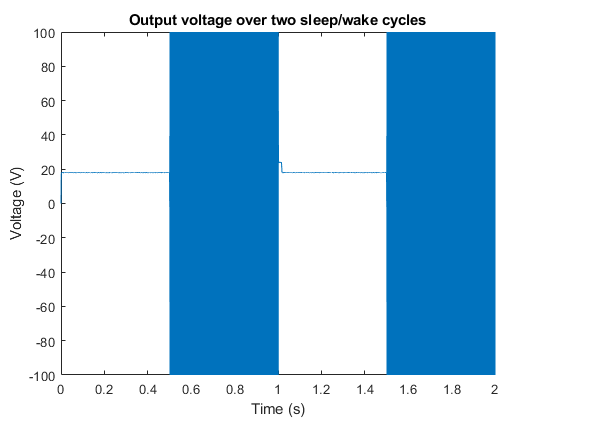

As it can be seen, even with the higher duty cycle, during active mode, the voltage remains constant at 18 volts. However, once the microcontroller goes into  low power mode, the output voltage goes unstable. It can be seen that for the first millisecond, the voltage is slightly higher than 18 volts, but then the PID system compensates and brings it back down to 18 volts.

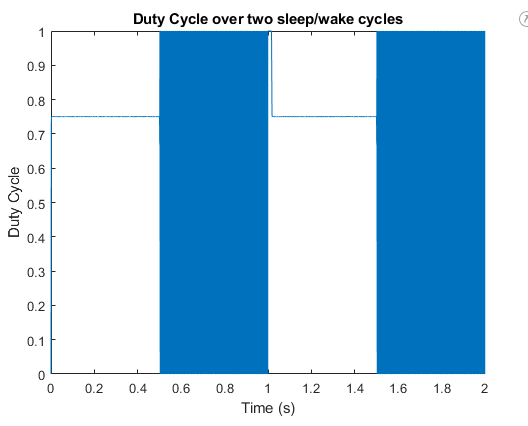

The figure above shows the duty cycle of the PID system with a 50% of the time spent on and 50% of the the time spent off. As it can be seen, the duty cycle is at approximately 75%. Exactly the same as when the system was off for a longer duration of time. It can also be seen that for the first millisecond after the the system re-enters a high power state, the duty cycle remains at 100% until dropping back down to 75%.

Next the circuit was held always at a high power state

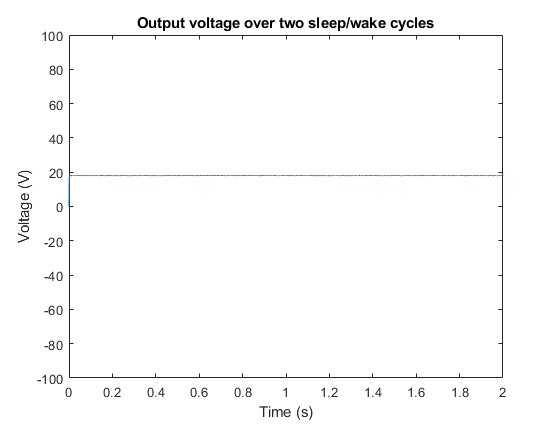

As it can be seen when the circuit is constantly being held in the high power state, the voltage output is a constant 18 volts. There is very little deviation to be seen. 

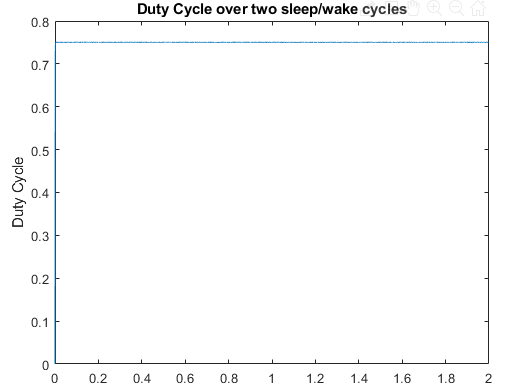

The duty cycle for the always active circuit shows a simular story, with the duty cycle being held at 75%. This is the exact same duty cycle observed in the other tests at the high load state. 

Overall, it appears changing the ratio of time the circuit is on to when it is off had no impact on the performance of the circuit. 

**Performance Analysis of Buck Converter at Different Current Values**

**A) System stability at different load currents**

To get a clear understanding of how the PID componsated buck converter performs with different load resistances, a MATLAB script was created that collected data from the componsated buck converter with different load resistances. First, we wanted to see for which current values the response of the buck converter was stable for. To accomplish this, the difference in magnitude was taken in the last 10 values from the simulation using the diff command in matlab. The simulation was suffiently long such that the system would be in the steady state far sooner than when these 10 measurements were taken. If the maximum differerence in the last 10 values was near zero, that means the system is stable at this current value, if the maximum difference is large, then the system is unstable at this current value.

As it can be seen the difference in the last 10 values appoaches zero when the current is approximately 50mA, signifigantly higher than the 0.1mA attempted to be used above. At current values below this, the system is seen to be occilating, indicated by the high difference in the last 10 values. While after 50mA, the system remains stable up to and beyond 1.8 amps (the graph was cut off at 0.4 for clarity). This explains why the system was functional when the load current was 100mA but not when the load current was 0.1mA.

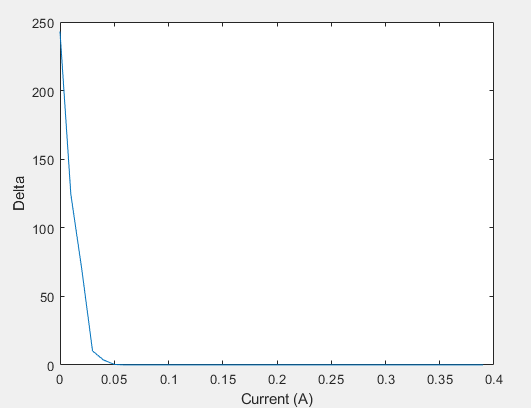

**Difference in the last 10 sampled values when system was supposedly in steady state**

The next figure plots the voltage output verses the load current. The output voltage measurement was taken at the final sampled value of the system, far after when the system should be in steady state. 

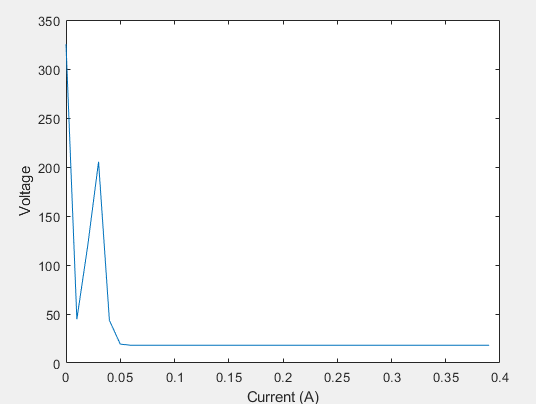

**Input Current VS Output Voltage**

This graph tells a very simular story to the steady state delta graph. The output is unstable until approximately 50 mA, when the system begins to output a steady 18 volts. This reinforces the fact that when the load current was only 0.1mA, the system was unstable and could not deliever a steady 18 volts to the output.

**B) Stable output charecteristics as a function of input current**

Next, out the input current values that are stable, I wanted to see how the output voltage changed as a function of the input current. To make the graphs rescale, I removed the unstable low current values from the graph for easier analyisis. The dashed line on each of the graphs represents the charecteristics at the "tuned" load current of 180mA. 

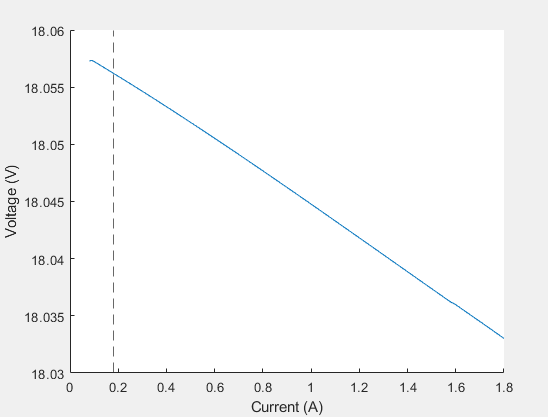

**Output Voltage VS Input Current**

The graph above shows the output voltage as a function of the input current. It can be seen as current increases, the output voltage from the buck converter begins to decrease as it has a harder time componsating for the higher input current. However, this decrease is on the order of tens of millivolts. 

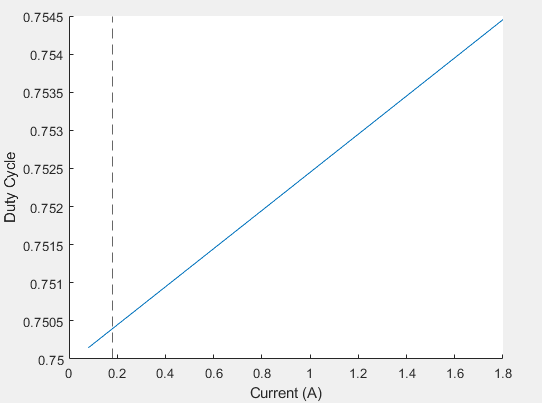

**Duty Cycle VS Input Current**

This graph shows the duty cycle as a function of input current. As expected considering the previous graph, as the input current increases, the duty cycle also increases to keep up with the higher load. However, this increase is negligable. 